# NACA airfoil wing

Finite element model from the following reference:

Jain, S., Tiso, P., Rutzmoser, J. B., & Rixen, D. J. (2017). A quadratic manifold for model order reduction of nonlinear structural dynamics. *Computers & Structures*, *188*, 80–94. [https://doi.org/10.1016/J.COMPSTRUC.2017.04.005](https://doi.org/10.1016/J.COMPSTRUC.2017.04.005)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

In this numerical example, the wing is clamped at one side, and the other side is free. And we place 2 control forces at Node A and Node B, as seen in the following figure.

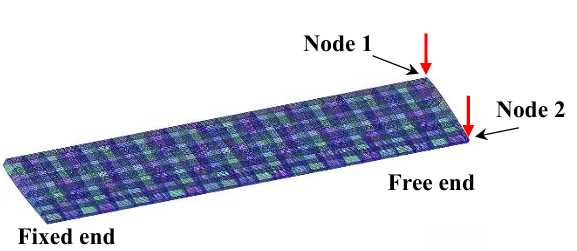

Some note: 

This example has more than 130,000 dofs, so, running the full model with the Newmark method requires a lot of memory and few days. Thus, if the reader wants to run this simulation, you'll need a computer with more than 64GB of RAM.

**system parameters**

clear all;
clc;
epsilon  = 0.1;

## generate model

% The key file "tensors_49968.mat" to build the NACA wing model is too
% large to upload. If the reader needs this file, please email the author.
[M,C,K,fnl,f_0,outdof] = build_model();
n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 133920


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 267840


## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',50,'Nmax',100,'notation','multiindex')

**Add external forcing and also control matrix**

Bext     = zeros(n,2); Bext(outdof(1),1)=1; Bext(outdof(2),2)=1; 
% epsilon  = 0.1;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 50 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.264041e-03
modal damping ratio for 4 mode is 3.612822e-03
modal damping ratio for 5 mode is 5.538531e-03
modal damping ratio for 6 mode is 9.251675e-03
modal damping ratio for 7 mode is 1.030470e-02
modal damping ratio for 8 mode is 1.036833e-02
modal damping ratio for 9 mode is 1.607384e-02
modal damping ratio for 10 mode is 1.634943e-02
modal damping ratio for 11 mode is 1.703258e-02
modal damping ratio for 12 mode is 2.195194e-02
modal damping ratio for 13 mode is 2.217650e-02
modal damping ratio for 14 mode is 2.263341e-02
modal damping ratio for 15 mode is 2.265647e-02
modal damping ratio for 16 mode is 2.269624e-02
modal damping rati

## SSM Reduced dynamics - autonomous part

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
masterModes = [1,2]; 
S.choose_E(masterModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 1068
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5
These are in resonance with the follwing eigenvalues of the master subspace
  -0.0587 +29.3428i
  -0.0587 +29.3428i
  -0.0587 +29.3428i
  -0.0587 +29.3428i
  -0.0587 -29.3428i
  -0.0587 -29.3428i
  -0.0587 -29.3428i
  -0.0587 -29.3428i
sigma_in = 1068


order = 3; % Approximation order
[W_0,R_0] = S.compute_whisker(order);
auData = construct_autoData(DS, masterModes, R_0);

## Linear model order reduction analysis

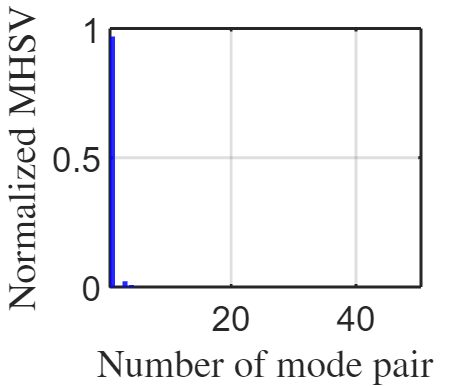

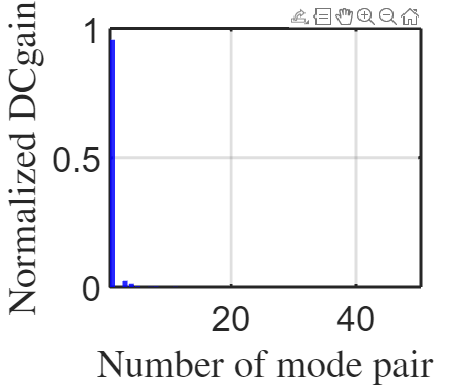

MHSV sum of the first 2 pair
    0.9696
DCgain sum of the first 2 pair
    0.9568


res = 1×2 cell 数组
    {50×1 double}    {50×1 double}

res = Linear_MOR(DS,50);

## Free Vibration

load("z0_static3.mat","z0")
tf     = 1; nsteps = 5000;
om = 2*pi/tf;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

## Closed loop control with 2 receding horizons

**Time interval - 1**

% control parameters
cont   = struct();
cont.Q    = 1e4*speye(2*n);
cont.Rhat = 100*speye(2);
cont.Mhat = 0e1*speye(2*n); 

nsteps = 2500;
t0 = 0;
t1 = 0.5;
tspan1 = linspace(t0,t1,nsteps);
tic
traj1   = NACAWing_LQR(DS,z0,'linear',tspan1,auData,W_0,masterModes,1:2,cont);
toc
ufun  = @(t) transpose(interp1(traj1.time,traj1.ut',t,'linear','extrap'));
    set(DS,'u',ufun);
tic
[tfull1, xfull1, xkf,xt1] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0,'ts',t0);
toc 
xf = xkf';

**Time interval - 2**

t2 = 1;
tspan2 = linspace(t1,t2,nsteps);
tic 
traj2   = NACAWing_LQR(DS,xf,'linear',tspan2,auData,W_0,masterModes,1:2,cont);
toc
ufun  = @(t) transpose(interp1(traj2.time,traj2.ut',t,'linear','extrap'));
    set(DS,'u',ufun);
tic
[tfull2, xfull2, xkf, xt2] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',t1);
toc

**Plot - Node 1**

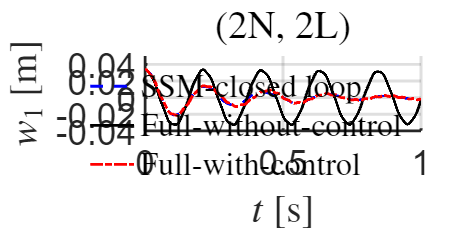

figure; hold on
plot(tfullwo, xfullwo(:,1),'k-','DisplayName','Full-without-control','LineWidth',2);
plot([traj1.time,traj2.time], [traj1.zt(1,:), traj2.zt(1,:)],'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfull1,tfull2], [xfull1(:,1); xfull2(:,1)],'r-.','DisplayName','Full-with-control','LineWidth',2);
xlim([0, 1])
ylim([-0.04, 0.05])
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$w_1$ [m]');
ylabel(zk,'Interpreter','latex');
title('(2N, 2L)', 'Interpreter','latex')
legend('show','Interpreter',"latex"); legend boxoff
set(gca,'FontSize',24); grid on

**Plot - control inputs**

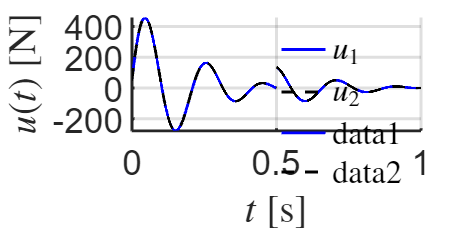

figure; hold on;
plot([traj1.time, traj2.time], [traj1.ut(1,:), traj2.ut(1,:)],'b-','DisplayName','$u_1$','LineWidth',2)
plot([traj1.time, traj2.time], [traj1.ut(2,:), traj2.ut(2,:)],'k--','DisplayName','$u_2$','LineWidth',2)
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [N]','Interpreter','latex')
legend('show','Interpreter',"latex"); legend boxoff
set(gca,'FontSize',24); grid on, axis tight